# Midterm Question #

**Author: Keith Chester**

**E-mail: kchester@wpi.edu**

## Methods

We are looking to use forward kinematics to create a model for the following robotic arm:

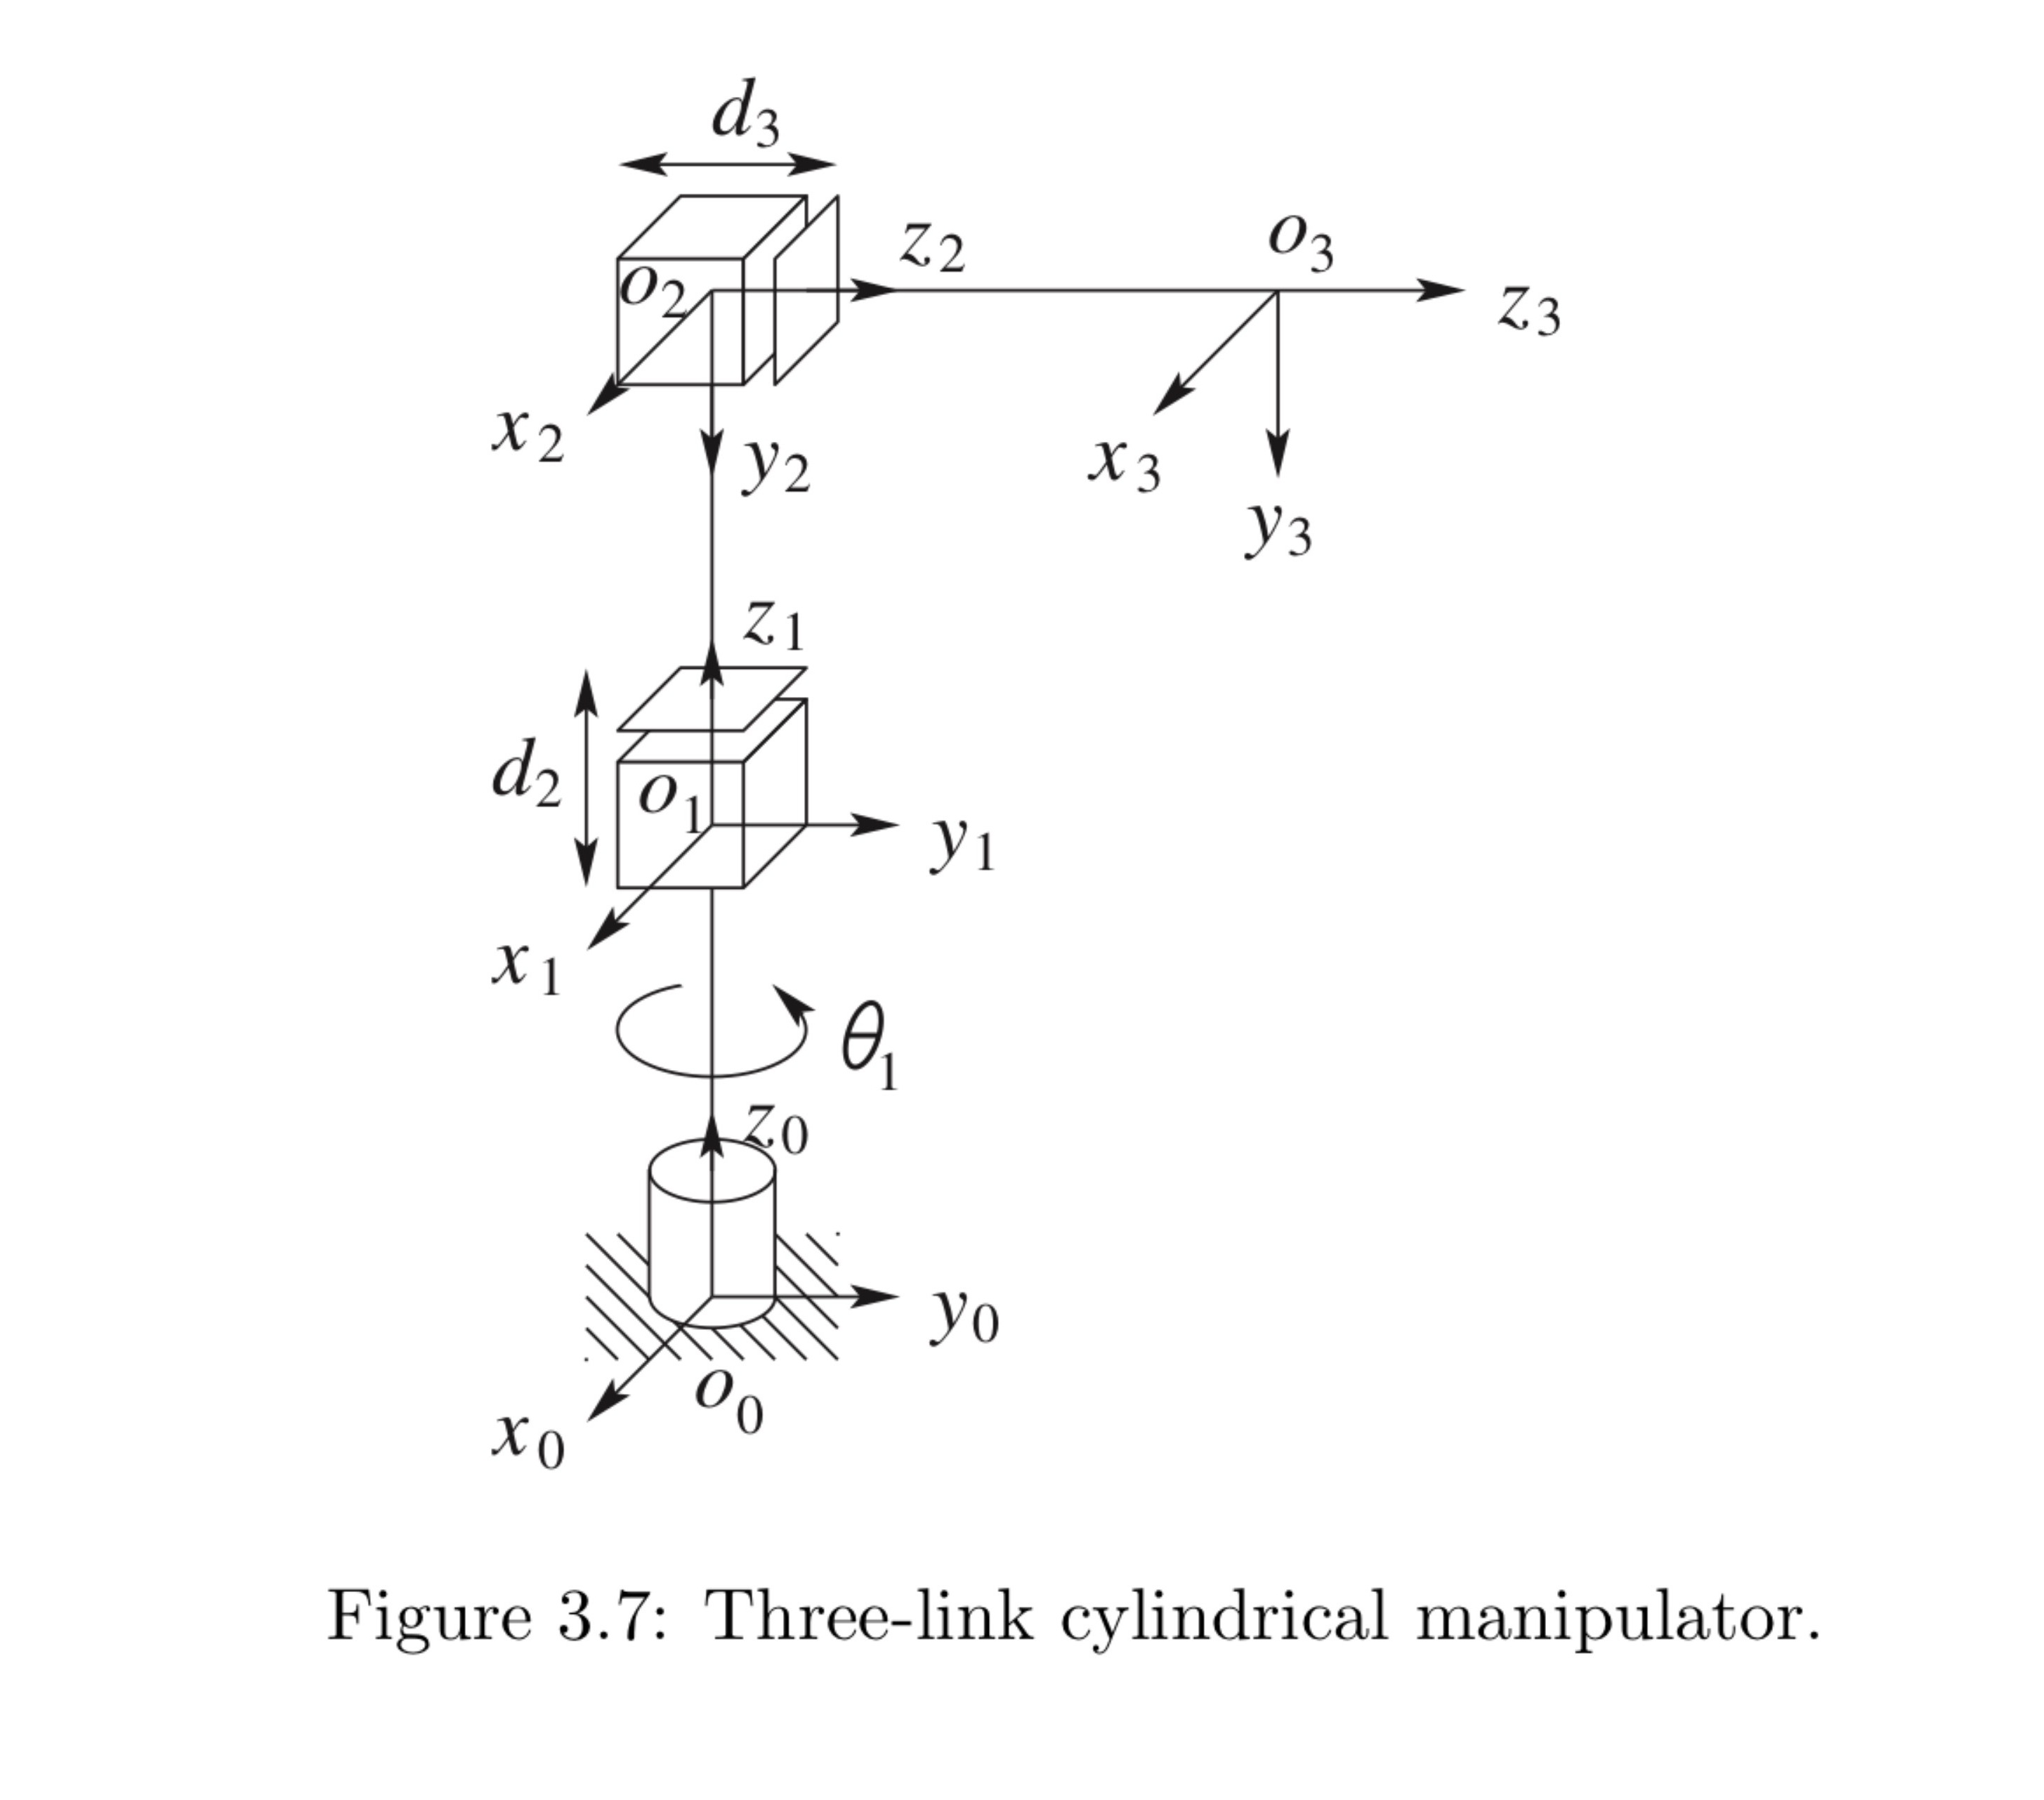

**PICK ONE**

We will be adding coordinate axes to meet the Denavit–Hartenberg (DH) Convention, which will make generating transformation matricies for between links of the robot arm simple and standardized.

OR

We will be making use of the axes provided in the robot diagram, as they already follow Denavit–Hartenberg (DH) Convention. With this convention of labeling coordinate axes, generating transformation matricies between links of the robot arm will be simple.

If we define the rotations of the arm as $\theta_1$, $\phi$, and $\psi$, respectively for revolute joints, and $d_1$, $d_2$ and $d_3$, respectively, for prismatic joints.

With this, we can find the transformation matrix between each link.

syms theta phi psi d1 d2 d3 a1 a2 a3 a4

dh_table = {
    [phi     d1  a1      pi],
    [theta   0   a2      0 ],
    [0       d2  0       0 ],
    [0       d3  0       0 ],
}

dh_table = 4×1 cell array
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}



A1 = transform_from_dh_row(dh_table, 1, true)

$$A1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = transform_from_dh_row(dh_table, 2, true)

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & a_{2}\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & a_{2}\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = transform_from_dh_row(dh_table, 3, true)

$$A3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 = transform_from_dh_row(dh_table, 4, true)

$$A4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The transformation matricies for each link is thus:

PASTE HERE.

From here, we can gather the transformation matrix from the base 0 frame to each coordinate frame throughout the arm. We can find these by multiplying through the link transformation matricies. As such:


$$\begin{array}{l}
H_1^0 =A_1 \\
H_2^0 =A_1 A_2 \\
H_3^0 =A_1 A_2 A_3 \\
H_4^0 =A_1 A_2 A_3 A_4 
\end{array}$$


or, essentially:

H_0_1 = A1

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_2 = simplify(A1 * A2)

$$H\_0\_2 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_3 = simplify(A1 * A2 * A3)

$$H\_0\_3 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}-d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_4 = simplify(A1 * A2 * A3 * A4)

$$H\_0\_4 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}-d_{2}-d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

PASTE HERE delete above?

Once we have these transformation matricies, we can begin to draw the arm at each stage of the simulation by calculating the locations of each axis frame within coordinate frame of the 0th base frame for each step.

## Results

Let us first set several of the variable length and sizes. Static variables, such as  BLA H BLAH

a1 = 1

a1 = 1

a2 = 1

a2 = 1

We'll be moving the joints according to the following range BLAH BLAH

% RAnge me
steps = 180;

Finally, we'll generate an animation/simulation of our arm as designed:

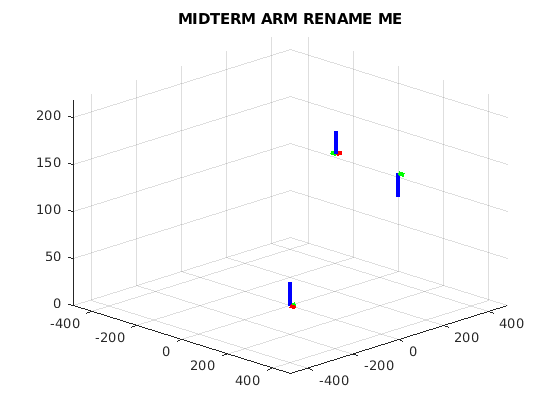

Error using line
Value must be a vector of numeric type.

Error in forward-kinematics-draft>draw_coordinate_axis (line 160)
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);

 

animation_length_seconds = 5;


phi = 90;
theta = 0;
d1 = 0;
phi_delta = -180 / 180;
theta_delta = -90 / 180;
d1_delta = 100 / 180;

figure
title("MIDTERM ARM RENAME ME")
grid on
hold on
axis([-480 480 -480 480 0 220])
view([45 25])
lines = [];

for step = 1:steps
    % Clear previous lines
    for index = 1:length(lines)
        delete(lines(index));
    end
    lines = [];
    
    % Set up our dh table for the step
    dh_table = {    %theta      %d      %a      %alpha
                 [  phi         146     205     0   ],
                 [  theta       -41     275     180 ],
                 [  0           d1       0      0   ]
               };
    
    A1 = transform_from_dh_row(dh_table, 1);
    A2 = transform_from_dh_row(dh_table, 2);
    A3 = transform_from_dh_row(dh_table, 3);
    
    % Calculate our H_02 and H_0_3
    H_0_1 = A1;
    H_0_2 = A1 * A2;
    H_0_3 = A3 * A4;
    
    % Draw coordinate axes
    [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3, 25, 'red', 'green', 'blue');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    % Draw links
    origin = [ 0; 0; 0; 1; ];
    corner_1 = origin + [0; 0; 146; 0;];
    shoulder = H_0_1 * origin;
    corner_2 = H_0_1 * [cosd(theta)*275; sind(theta)*275; 0; 1;];
    elbow = H_0_2 * origin;
    wrist = H_0_3 * origin;
    lines(end+1) = line('XData', [origin(1) corner_1(1)], 'YData', [origin(2) corner_1(2)], 'ZData', [origin(3) corner_1(3)], 'Color', 'black', 'LineWidth', 4);
    lines(end+1) = line('XData', [corner_1(1) shoulder(1)], 'YData', [corner_1(2) shoulder(2)], 'ZData', [corner_1(3) shoulder(3)], 'Color', 'black', 'LineWidth', 4);
    lines(end+1) = line('XData', [shoulder(1) corner_2(1)], 'YData', [shoulder(2) corner_2(2)], 'ZData', [shoulder(3) corner_2(3)], 'Color', 'black', 'LineWidth', 4);
    lines(end+1) = line('XData', [corner_2(1) elbow(1)], 'YData', [corner_2(2) elbow(2)], 'ZData', [corner_2(3) elbow(3)], 'Color', 'black', 'LineWidth', 4);
    lines(end+1) = line('XData', [elbow(1) wrist(1)], 'YData', [elbow(2) wrist(2)], 'ZData', [elbow(3) wrist(3)], 'Color', 'magenta', 'LineWidth', 4);
    
    % Mark the actuator endpoint
    plot3(wrist(1), wrist(2), wrist(3), 'o')

    phi = phi + phi_delta;
    theta = theta + theta_delta;
    d1 = d1 + d1_delta;
        
    pause(animation_length_seconds/steps)
    
end


hold off

### Functions and Classes

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end